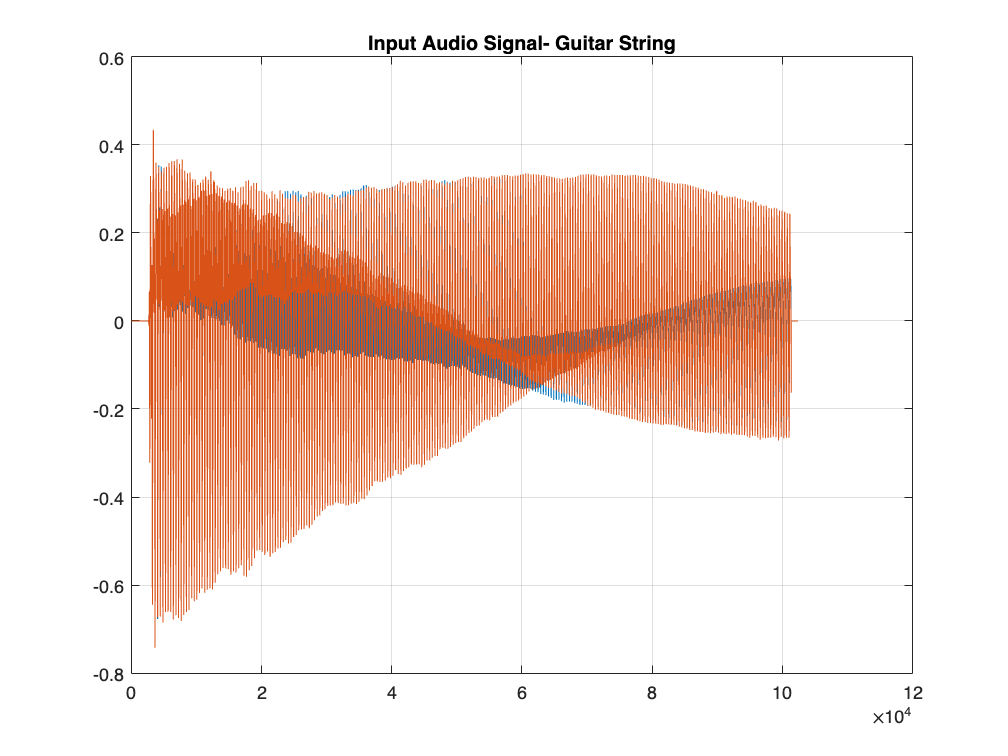

% CODES FOR STANDARD TUNING 

% Asking user to select audio file
filename = input("Enter the name of the audio file (including the file type): ", 's');

% Read in the audio signal
[y, fs] = audioread(filename);

% Play the audio 
sound(y, fs);

% Wait for the original sound to finish playing
pause(length(y)/fs);

n = length(y)-1; % determining last index of the array
f = 0:fs/n:fs; % time vector 
bh = blackmanharris(n+1); %Blackman-Harris Window
h = hanning(n+1); %Hanning Window

figure(1);
plot(y); grid on; title('Input Audio Signal- Guitar String')

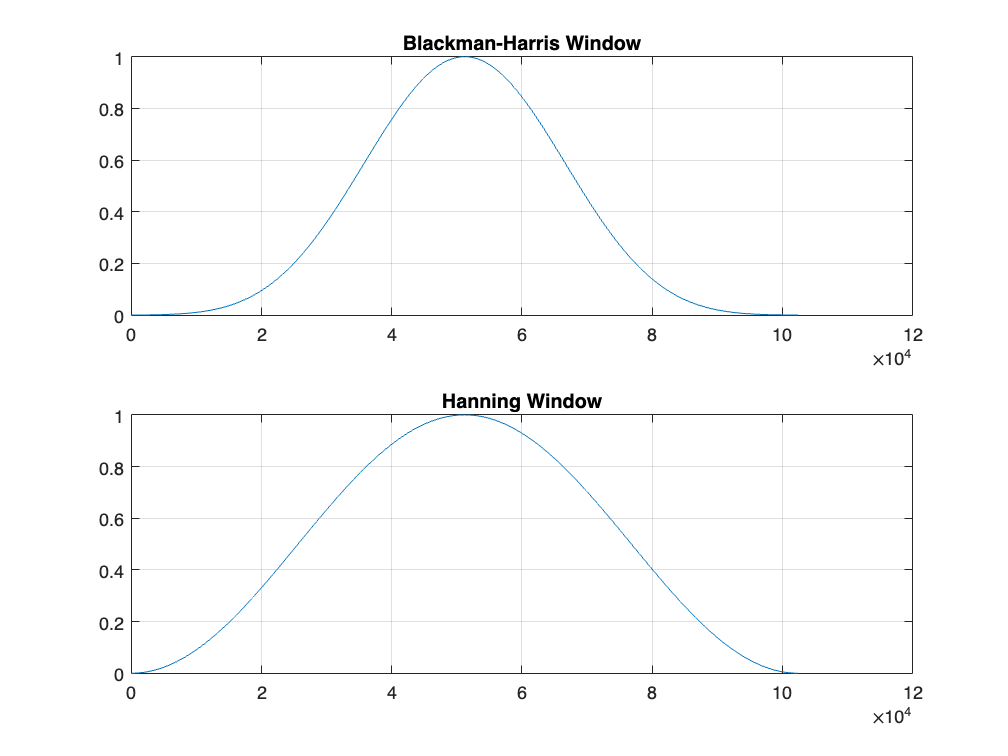

subplot(211); plot(bh); grid on; title('Blackman-Harris Window');
subplot(212); plot(h); grid on; title('Hanning Window');

% Declaring standard fundamental frequency
E2 = 82.41;
A2 = 110;
D3 = 146.83;
G3 = 196.00;
B3 = 246.94;
E4 = 329.63;

% Declaring the bounds to be used for frequency filters so that the
% frequency has a tolerance to follow (For example, an input audio with a
% frequency of 85 will still be applicable in E2 for tune down and A2 for
% tune up. 
E2A2 = mean([E2 A2]);
A2D3 = mean([A2 D3]);
D3G3 = mean([D3 G3]);
G3B3 = mean([G3 B3]);
B3E4 = mean([B3 E4]);

% Declaring filter coefficients
E2filter = (1.*(f<E2A2).*(f>70))'; % creating a column vector that are true for elements of "f" that are greater than 70 and less than E2A2 (96.21).
A2filter = (1.*(f>E2A2).*(f<A2D3))';
D3filter = (1.*(f>A2D3).*(f<D3G3))';
G3filter = (1.*(f>D3G3).*(f<G3B3))';
B3filter = (1.*(f>G3B3).*(f<B3E4))';
E4filter = (1.*(f>B3E4).*(f<350))';

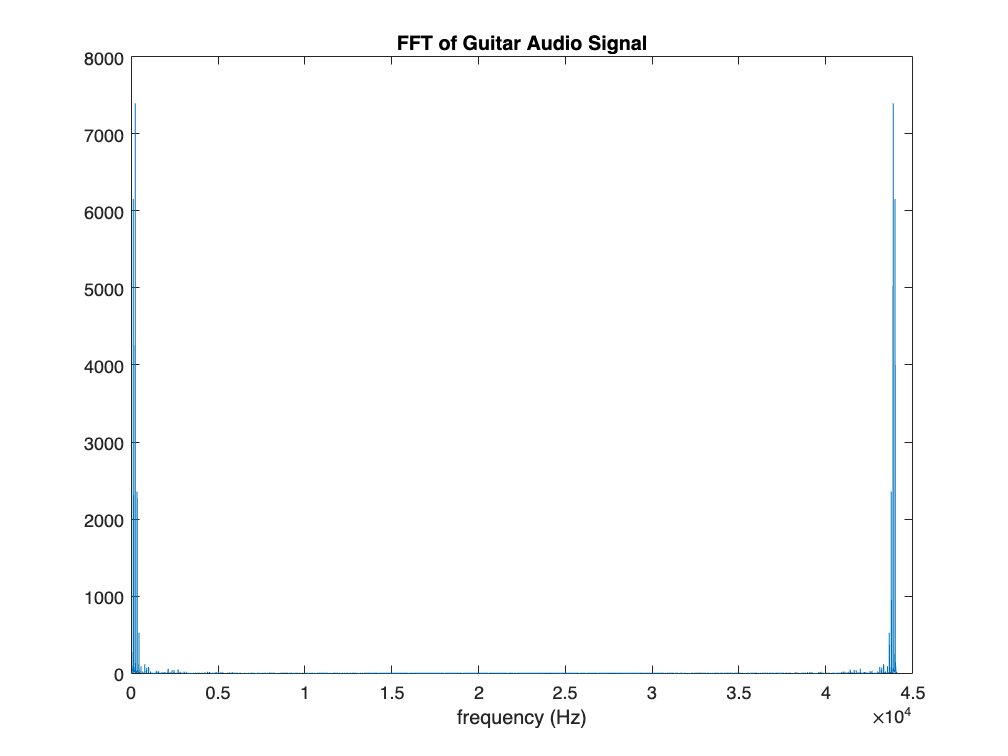

%FFT
y = abs(fft(y));
extract = y(:,1); %extract one column
figure(2); 
plot(f,extract); title('FFT of Guitar Audio Signal'); xlabel('frequency (Hz)');